# Predittore ad 1 e 2 passi in avanti per un processo ARMA non in forma canonica

Dato il procersso stocastico stazionario descritto dal modello


$$
v(t)+\frac{7}{30} v(t-1)-\frac{29}{150} v(t-2) - \frac{11}{150} v(t-3) - \frac{1}{150}\,v(t-4)=
\eta(t)+\frac{80}{9} \eta(t-1) -\eta(t-2)\quad \eta(\cdot) \sim \text{WN}\left(0,\,4\right) $$


si chiede di

- verificare che il modello assegnato non è un fattore spettrale canonico;

- determinare una descrizione per il processo con un modello che sia fattore spettrale canonico;

- utilizzando la forma canonica, determinare l'espressione del predittore ad un passo in avanti e quella del predittore a due apssi in avanti per il processo assegnato;

- determinare la varianza dell' errore di predizione per entrambi i predittori (ad uno ed a due passi);

- nel caso del predittore a due passi, determinare anche la funzione di correlazione del processo dell'errore di predizione.

clear 
close all
clc

var_eta = 4; % varianza del rumore bianco del modello assegnato

z = tf('z',1);

a1 = 7/30;
a2 = -29/150;
a3 =-11/150;
a4 = -1/150;

c1 =80/9;
c2 = -1;

W_z =(z^2 + c1*z + c2) /(z^4 + a1*z^3 + a2*z^2 + a3*z + a4)

W_z =
 
                   z^2 + 8.889 z - 1
  ----------------------------------------------------
  z^4 + 0.2333 z^3 - 0.1933 z^2 - 0.07333 z - 0.006667
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


zpk(W_z)

ans =
 
        (z+9) (z-0.1111)
  ----------------------------
  (z-0.5) (z+0.3333) (z+0.2)^2
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


[Nz, Dz] = tfdata(W_z, 'v');      % the polynomials coefficients, ordered in deecreasing powers of "z"

Dz = Dz ./Dz(1) % the denominator is now a monic polynomial

Dz =     1.0000    0.2333   -0.1933   -0.0733   -0.0067


Nz =  Nz./Dz(1)

Nz =          0         0    1.0000    8.8889   -1.0000


sum_ak2 = sum(Dz.^2)

sum_ak2 = 1.0972

alphaPoly = zeros(size(Dz));
alphaPoly(1) = 1; % by construction alpha_0 = 1
N = numel(Dz)-1;
for i=2:N+1
    dummy_alpha_i = 0;
    for k=1:N
        if ((k+i-1)<=N+1)
            dummy_alpha_i = dummy_alpha_i+Dz(k)*Dz(k+i-1);
        end
    end % for k
    alphaPoly(i) = dummy_alpha_i/sum_ak2;
end % for i
disp(alphaPoly)

    1.0000    0.1849   -0.1906   -0.0683   -0.0061





betaPoly = zeros(size(Dz));


for j=1:N+1
    dummy_beta_j = 0;
    for k=1:N
        if ((k+j-1)<=N+1)
            dummy_beta_j = dummy_beta_j+Nz(k)*Nz(k+j-1);
        end
    end % for k
    betaPoly(j) = var_eta*dummy_beta_j/sum_ak2;
end % for i
disp(betaPoly)

  291.6847         0   -3.6455         0         0



betaPoly = betaPoly(1:3);
[r, Cz_coeffs, Az_coeffs] = L8_spectrFactAlg(fliplr(betaPoly), fliplr(alphaPoly)) 

r = 319.9994

Cz_coeffs =     1.0000    0.0000   -0.0125


Az_coeffs =     1.0000    0.2333   -0.1933   -0.0733   -0.0067


hat_Wz_1 = tf(Cz_coeffs, Az_coeffs, 1, 'Variable','z^-1')

hat_Wz_1 =
 
                1 + 2.776e-17 z^-1 - 0.0125 z^-2
  ------------------------------------------------------------
  1 + 0.2333 z^-1 - 0.1933 z^-2 - 0.07333 z^-3 - 0.006667 z^-4
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Adesso che abbiamo la forma canonica, calcoliamo il predittore ad un passo

[N1z, D1z] = tfdata(hat_Wz_1, 'v')

N1z =     1.0000    0.0000   -0.0125         0         0


D1z =     1.0000    0.2333   -0.1933   -0.0733   -0.0067


[QQ,R] = poly_long_division(N1z, D1z, 1)

QQ = 1

R =          0   -0.2333    0.1808    0.0733    0.0067


Rz1 = R(2:end);
Qz1 = QQ;
hat_W1z_1 = tf(Rz1, D1z, 1, 'Variable','z^-1') % using ascending powers of z^-1 

hat_W1z_1 =
 
      -0.2333 + 0.1808 z^-1 + 0.07333 z^-2 + 0.006667 z^-3
  ------------------------------------------------------------
  1 + 0.2333 z^-1 - 0.1933 z^-2 - 0.07333 z^-3 - 0.006667 z^-4
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Ora calcoliamo il predittore a due passi (stessa cosa di prima)

[QQ,R] = poly_long_division(N1z, D1z, 2)

QQ =     1.0000   -0.2333


R =          0         0    0.2353    0.0282   -0.0104   -0.0016


Rz2 = R(3:end);
Qz2 = QQ;
hat_W1z_1 = tf(Rz2, D1z, 1, 'Variable','z^-1') % using ascending powers of z^-1 

hat_W1z_1 =
 
      0.2353 + 0.02822 z^-1 - 0.01044 z^-2 - 0.001556 z^-3
  ------------------------------------------------------------
  1 + 0.2333 z^-1 - 0.1933 z^-2 - 0.07333 z^-3 - 0.006667 z^-4
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Calcolo modello errore e varianza per un passo

il modello dell'errore per il nostro predittore di un ARMA, si comporta come un MA(1) (rumore bianco), quindi uso le formule del MA(1) per calcolare varianza e autocorrelazione

EzNUM = Qz1;
EzDEN = 1;
EzModel = tf(EzNUM, EzDEN, 1, 'Variable', 'z^-1') %useful only for seeing the result

EzModel =
 
  1
 
Static gain.
Model Properties


pred_err_var = EzNUM*EzNUM'*r 

pred_err_var = 319.9994

% usiamo r e non la var di partenza del bianco perchè abbiamo portato il
% filtro in forma canonica e quindi è cambiata

Calcolo modello errore e varianza per due passi

EzNUM = Qz2;   % the MA model of the prediction error using ascending powers of z^-1
EzDEN = [1 0]; 
EzModel = tf(EzNUM, EzDEN, 1, 'Variable', 'z^-1') %useful only for seeing the result

EzModel =
 
  1 - 0.2333 z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


pred_err_var = EzNUM*EzNUM'*r

pred_err_var = 337.4216

Calcolo funzione autocorrelazione MA(1) dell'errore

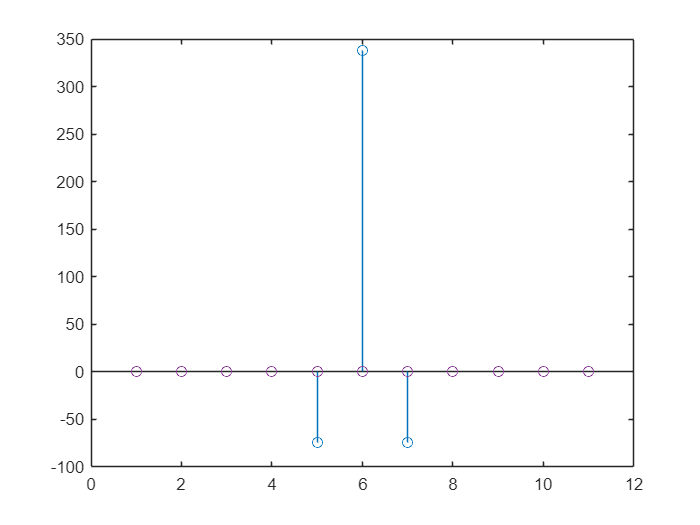

c0 = Qz2(1);
c1 = Qz2(2);

gamma0 = (1 + c1^2)*r;
gamma1 = c0*c1*r;

gamma_k = zeros(11);
gamma_k(6) = gamma0;
gamma_k(5) = gamma1;
gamma_k(7) = gamma1; 
stem(gamma_k)